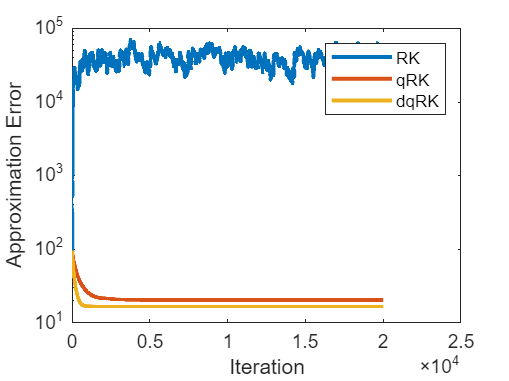

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Add functions path
addpath('Functions\')

% Algorithm parameters
MAX_ITERATIONS  = 20000;
q1              = 4/5;
beta            = 48/958;
q0              = 3/5;

[m,n,A,x,b] = SystemSetup(1,1,"custom",beta,"Matrix\ash958.mat",0,100,1);

%------------------------------------------------------
% Data collection values
err     = zeros(MAX_ITERATIONS+1, 1);
qerr    = zeros(MAX_ITERATIONS+1, 1);
derr    = zeros(MAX_ITERATIONS+1, 1);

xks     = zeros(n, MAX_ITERATIONS+1);
qxks    = zeros(n, MAX_ITERATIONS+1);
dxks    = zeros(n, MAX_ITERATIONS+1);

% Initialization
xk  = zeros(n, 1);
xks(1:n,1)  = xk;
qxks(1:n,1) = xk;
dxks(1:n,1) = xk;

err(1)      = norm(x - xk)^2;
qerr(1)     = norm(x - xk)^2;
derr(1)     = norm(x - xk)^2;

% Run RK, qRK, dqRK for MAX_ITERATIONS
for iter = 1:MAX_ITERATIONS
    tmp     = RKalgstep(A,xks(1:n,iter),b);
    qtmp    = qRKalgstep(A,qxks(1:n,iter),b,q1);
    dtmp    = dqRKalgstep(A,dxks(1:n,iter),b,q0,q1);
       
    %   Data collection
    err(iter + 1)       = norm(x - tmp)^2;
    qerr(iter + 1)      = norm(x - qtmp)^2;
    derr(iter + 1)      = norm(x - dtmp)^2;

    xks(1:n,iter + 1)   = tmp;
    qxks(1:n,iter + 1)  = qtmp;
    dxks(1:n,iter + 1)  = dtmp;
end

% Error graphs
errgraph = semilogy(err,'DisplayName','RK','LineWidth', 2);
hold on
semilogy(qerr,'DisplayName','qRK', 'LineWidth', 2);
semilogy(derr,'DisplayName','dqRK', 'LineWidth', 2);

xlabel("Iteration")
ylabel("Approximation Error")
legend
hold off

% Save tikz plot
filename = "Figs\error_horizon_comparisons";
saveas(errgraph, filename, 'fig');
filename = convertStringsToChars(filename+".tex");
matlab2tikz(filename)